## Deep Learning Project: **Automated Speech Recognition**

**Name : Muzhaffar Maruf Ibrahim**

**Student Number :  230118670**

### **1.1 Setting Up Random Number Generator**

This step specifies the seed for the MATLAB® random number generator. For example, rng(1) initializes the `Mersenne Twister` generator using a seed of 1. By setting the same seed, different runs of the simulation will produce identical results, assuming all other variables remain constant

clear all;

%Setting up the random number generator using Mersenne Twister method to get the constant value
rng(1,'twister');

### **1.2 Load the spectogram data **

The spectogram data is divided in to two part, which consist of Training data and Validation data. The data is consisted of 12 different voice classes where consist of background, down, go, left, no, off, on, right, stop, unknown, up, and yes. 

- Training data: Data that is used to train, or fit, a machine learning model in order to make predictions or perform tasks based on this data. 

- Validation data: Data that is used to evaluate a model's performance during the training process which indicated by accuracy. 

The validation data encompasses a more substantial portion compared to the training data. This discrepancy could have implications for the performance and generalizability of the model, as the proportion of data used for validation exceeds that of training.

% create an image data store from the raw images 
imdsTrain = imageDatastore('speechImageData\TrainData',"IncludeSubfolders",true,"LabelSource","foldernames")

imdsTrain =   ImageDatastore with properties:

                       Files: {
                              ' ...\Project\speechImageData\TrainData\background\image_train_1662.png';
                              ' ...\Project\speechImageData\TrainData\background\image_train_1663.png';
                              ' ...\Project\speechImageData\TrainData\background\image_train_1664.png'
                               ... and 1998 more
                              }
                     Folders: {
                              ' ...\Sem 2 (Spring)\Deep Learning\Project\speechImageData\TrainData'
                              }
                      Labels: [background; background; background ... and 1998 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"


% create an image validation data store from the validation images 
imdsVal = imageDatastore('speechImageData\ValData',"IncludeSubfolders",true,"LabelSource","foldernames")

imdsVal =   ImageDatastore with properties:

                       Files: {
                              ' ...\Project\speechImageData\ValData\background\image_val_1112.png';
                              ' ...\Project\speechImageData\ValData\background\image_val_1113.png';
                              ' ...\Project\speechImageData\ValData\background\image_val_1114.png'
                               ... and 1168 more
                              }
                     Folders: {
                              ' ...\Courses\Sem 2 (Spring)\Deep Learning\Project\speechImageData\ValData'
                              }
                      Labels: [background; background; background ... and 1168 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
        

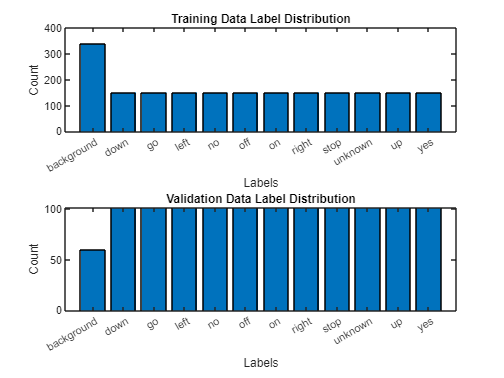


% Count labels in the training datastore
labelCountTrain = countEachLabel(imdsTrain);

% Count labels in the validation datastore
labelCountVal = countEachLabel(imdsVal);

% Plot for Training Data
subplot(2,1,1); % This will place the training data plot in the left pane
bar(labelCountTrain.Label, labelCountTrain.Count);
title('Training Data Label Distribution');
xlabel('Labels');
ylabel('Count');

% Plot for Validation Data
subplot(2,1,2); % This will place the validation data plot in the right pane
bar(labelCountVal.Label, labelCountVal.Count);
title('Validation Data Label Distribution');
xlabel('Labels');
ylabel('Count');

### 1.3  Image Preprocessing and Data Augmentation

This parameter ensures the application of a color preprocessing step to each image, specifically converting grayscale images into RGB format. This transformation is particularly advantageous if the original dataset predominantly consists of grayscale images, while the model in use is designed to process three-channel RGB images.

The size of the image is would be $98\times 50$ pixel which shown by the `OutputSize `from `dsVal` and `dsTrain.`

%Image preprocessing
image_size = [98 50];  
dsTrain = augmentedImageDatastore(image_size,imdsTrain,'ColorPreprocessing', 'gray2rgb');
dsVal = augmentedImageDatastore(image_size,imdsVal,'ColorPreprocessing', 'gray2rgb');

### 1.4 Performing Multi-objective network design using Bayesian Optimization

Since Deep Learning is consist of layers of interconnected nodes, it also could be called as Artifical Neural Network. It has a unique challenge with expensive computation in the evaluation since its calculate vast amount of processing data through many layers. 

To ensure the effectiveness of a machine learning model, it's crucial to find the optimal set of hyperparameters. Hyperparameters are external configurations to the model, unlike model parameters, which are learned from the data. They play a significant role in the learning process and the overall performance of the model. 

In pursuit of the lowest possible value of the loss function, which indicates the disparity between the predicted and actual outcomes, conducting hyperparameter optimization becomes a necessity. Here's the step-by-step:

- Define the objective function with the variable `NetworkTraining `

- $\hat{f} \left(\ldotp \right)\approx J\left(x\right)$ is the model objective function 

- $\hat{f} \left(\ldotp \right)\sim N\left(\mu_f \left(x\right),\sigma_f^2 \right)$is the bayesian model

- To update the process in order to maximise an acquisition function $x_{t+1} =\arg \;\max_x \alpha \left(x,\hat{f} \left(\ldotp \right)\right)$in order to determine the next point to evaluate the objective function which likely to improve minimization of loss value.     

#### 1.4.1 Define the Constant Parameter

 In this part, we need to define the parameters constant parameters which would be used in the network

- `num_classes = 12 : `Given that the database's output comprises 12 distinct classes, it's necessary to configure the network's output layer to match this number, ensuring that each category is adequately represented.

- `filter_size = 3 : `To effectively extract features from input data transformed into RGB format by the `augmentedImageDatastore` function, it is essential to employ three filters. Each filter is dedicated to extracting features from one color channel—Red, Green, or Blue—in the spectrogram data, ensuring a comprehensive analysis of the full color spectrum. 

- `timePoolSize = 12 : `Since the input is 2D data, we need to reduce the dimensionality or capture the most significant features along one specific axis of the data to make the network more computationally efficient.

- `dropout = 0.2 : ` Dropout is a regularization technique used in neural networks to prevent overfitting which during training, dropout randomly sets a fraction (in this case, 20%) of the input units to zero at each update of the training phase.

% Constant Parameter
num_classes = 12;  % number of classes
filter_size = 3;  % number of filters
timePoolSize = 12; % Pool Size
dropout_rate = 0.2; % The value of dropout layer
Maxpool_value = 3; % Define the number of Maxpool value

#### 1.4.2 Define the objective function of Bayesian Optimization

In this section, the `objective_function` will explore the optimal hyperparameters within specified ranges. it will evaluate the number of layers between 4 and 7, and the number of filters from 5 to 14, to determine the best configuration using `optimizeVariable`.

the `objective_function `is defined as a separated function outside which named as `trainNetworkForDeeplearning.m `

The result of bayesian optimization will be stored in `result_bayesopt. `

% Define the Objective Function
objective_function = @(x)trainNetworkForDeeplearning(x, dsTrain, dsVal, imdsVal, num_classes, num_filters, image_size, timePoolSize, dropout_rate, Maxpool_value)

objective_function = function_handle with value:
    @(x)trainNetworkForDeeplearning(x,dsTrain,dsVal,imdsVal,num_classes,num_filters,image_size,timePoolSize,dropout_rate,Maxpool_value)


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |   num_layers |  num_filters |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.26046 |      74.697 |     0.26046 |     0.26046 |            6 |            9 |
|    2 | Best   |     0.25705 |      60.323 |     0.25705 |     0.25839 |            4 |            9 |
|    3 | Best   |      0.2357 |      62.503 |      0.2357 |     0.23607 |            5 |           14 |
|    4 | Accept |      0.3006 |      59.702 |      0.2357 |     0.23585 |            4 |            6 |
|    5 | Accept |     0.27925 |      63.344 |      0.2357 |     0.23587 |            5 |           13 |


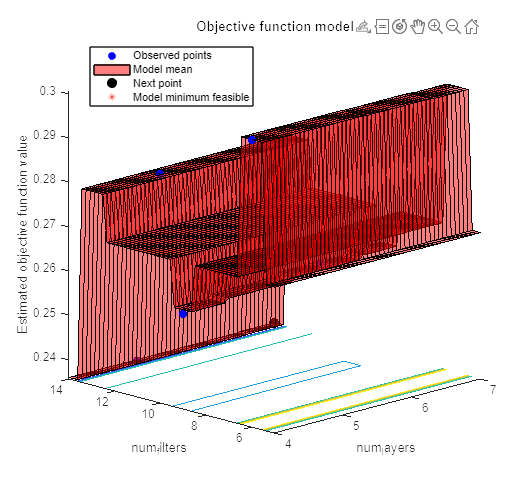

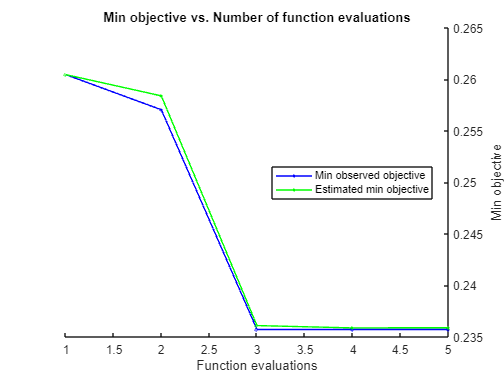


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 5 reached.
Total function evaluations: 5
Total elapsed time: 325.4579 seconds
Total objective function evaluation time: 320.5686

Best observed feasible point:
    num_layers    num_filters
    __________    ___________

        5             14     

Observed objective function value = 0.2357
Estimated objective function value = 0.23587
Function evaluation time = 62.5027

Best estimated feasible point (according to models):
    num_layers    num_filters
    __________    ___________

        5             14     

Estimated objective function value = 0.23587
Estimated function evaluation time = 63.8963



% Set up the Hyperparameter Space
hyperparameterSpace = [
    optimizableVariable('num_layers', [4, 7], 'Type', 'integer');
    optimizableVariable('num_filters', [5, 14], 'Type', 'integer')
];

% perform Bayesian optimization
result_bayesopt = bayesopt(objective_function, hyperparameterSpace, 'MaxObjectiveEvaluations', 5);

### 1.5 Implementing Ensemble Method (Bootstrap Aggregating)

Bagging is a distinct ensemble learning technique in which models are trained on various subsets of the original dataset. In this partciular case, 3 different model would be produced in the the process and constraint. However, even when using identical architecture and data, the model is likely to generate varying patterns of learning. This variation arises because the training process involves the random initialization of weights, leading to distinct learning pathways for each model.

%Establish the number of models to be utilized 
model_cell = 5

model_cell = 5


%Define the cell to stored the trained model
models_list = cell(1:model_cell)

models_list = 5-D cell array
models_list(:,:,1,1,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,2,1,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,3,1,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,1,2,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,2,2,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,3,2,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,1,3,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,2,3,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,3,3,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,1,4,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,2,4,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,3,4,1) = 

    {0×0 double}    {0×0 double}


models_list(:,:,1,1,2) = 

    {0×0 double}    {0×0 double}


models_list(:,:,2,1,2) = 

    {0×0 double}    {0×0 double}


models_list(:,:,3,1,2) = 

    {0×0 double}    {0×0 double}


models_list(:,:,1,2,2) = 

    {0×0 doubl

### 1.6 Defining Network Architecture

To establish the network's architecture, we will utilize the outcomes of Bayesian optimization to ensure the optimal quantities of filters and layers. This will be achieved by extracting the number of layers and number of filters from `result_bayesopt.XAtMinEstimatedObjective.num_layers` and `result_bayesopt.XAtMinEstimatedObjective.num_filters`, respectively.

% Execute the loop process for 5 different model
for model_index = 1:model_cell
    % get the best hyperparameters
    number_layers = result_bayesopt.NextPoint.num_layers;
    number_filters = result_bayesopt.NextPoint.num_filters;

Unrecognized function or variable 'num_layers'.

#### 1.6.1 Define the Input Network Layer

Since we had 3 channel input data that defined by RGB, we need to defined the `imageInputLayer `as $\lbrack 98\times 50\times 3\rbrack$ 

    % define the network input layers
    network_layer = [
        imageInputLayer([image_size 3])
    ];

#### 1.6.2 Establish Convolutional Layer

This loop constructs the layers of the CNN. For each layer from 1 to `num_layers`:

- A convolutional layer (`convolution2dLayer`) is added. This layer applies a number of filters (defined by `num_filters`) to the input. Each filter is of size `filter_size`, and 'Padding' is set to 'same' to ensure the output size is the same as the input size.

- A batch normalization layer (`batchNormalizationLayer`) follows, which normalizes the output of the convolutional layer, reducing internal covariate shift and improving training stability.

- A ReLU (Rectified Linear Unit) layer (`reluLayer`) is added next, introducing non-linearity to the network, allowing it to learn more complex patterns.

    % add the convolutional layers
    for i = 1:number_layers
        network_layer = [
            network_layer
            convolution2dLayer(filter_size, num_filters, Padding="same")
            batchNormalizationLayer
            reluLayer
        ];

To restrict the extent of max pooling and mitigate its potential reduction of the input data's spatial dimensionality, the application of max pooling will be limited to only the first three layers. 

        if i <= Maxpool_value
        network_layer = [
                network_layer
                maxPooling2dLayer(filter_size, Stride=2, Padding="same")
            ];
        end

        num_filters = num_filters * 2;  % double the number of filters for the next layer
    end
  
    % add the rest of the layers
    network_layer = [
        network_layer
        maxPooling2dLayer([timePoolSize,1])
        dropoutLayer(dropoutProb)
        fullyConnectedLayer(num_classes)
        softmaxLayer
        classificationLayer
    ];

Network Structure :

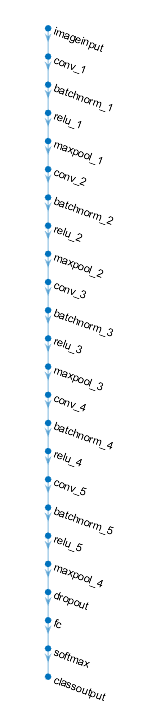

The `trainingOptions` function specifies the configuration for training the network, including the use of the Adam optimizer, mini-batch size, learning rate, number of epochs, data shuffling method, validation data and frequency, verbosity, progress plots, and the execution environment (GPU). 

In the part of training optimisation, Adaptive Moment Estimation (Adam) will be utilized. The Adam optimization algorithm is a popular method for training deep learning models, particularly neural networks. It combines ideas from two other popular optimization techniques: Adaptive Gradient Algorithm (AdaGrad) and Root Mean Square Propagation (RMSProp).


$$m_{\ell } =\beta_1 m_{\ell -1} +\left(1-\beta_1 \right)\nabla E\left(\theta_{\ell } \right)$$



$$v_{\ell } =\beta_2 v_{\ell -1} +\left(1-\beta_2 \right){\left\lbrack \nabla E\left(\theta_{\ell } \right)\right\rbrack }^2$$


Decay rate is defined using `GradientDecayFactor (`$\nabla E\left(\theta_{\ell } \right)$) and `SquaredGradientDecayFactor `${\left\lbrack \nabla E\left(\theta_{\ell } \right)\right\rbrack }^2$.

Adam uses the moving averages to update the network parameters as


$$\theta_{\ell +1} =\theta_{\ell } -\frac{\alpha m_l }{\sqrt{v_l }+\varepsilon }$$


If gradients over many iterations are similar, then using a moving average of the gradient enables the parameter updates to pick up momentum in a certain direction. If the gradients contain mostly noise, then the moving average of the gradient becomes smaller, and so the parameter updates become smaller too.

Afterward, each five model will be stored in `model_list. `

    % training options 
    options = trainingOptions('adam', ...
        "MiniBatchSize",30, ...
        'InitialLearnRate',0.001, ...
        'MaxEpochs',15, ...
        'Shuffle','every-epoch', ...
        'ValidationData',dsVal, ...
        'ValidationFrequency',10, ...
        'Verbose',true, ...
        'Plots','training-progress',...
        'ExecutionEnvironment','gpu');

    % train each model network
    net = trainNetwork(dsTrain,layers,options);
    
    % store the trained network in the prepared storage of models_list
    models_list{model_index} = net;
end

Given that five models have been established, the accuracy of each model will be evaluated through a classification process. This will be conducted using the `classify` command, with the outcomes of the classifications being stored in the variable `YPreds.`

The Result of 5 trained networks:

- 1st Training

        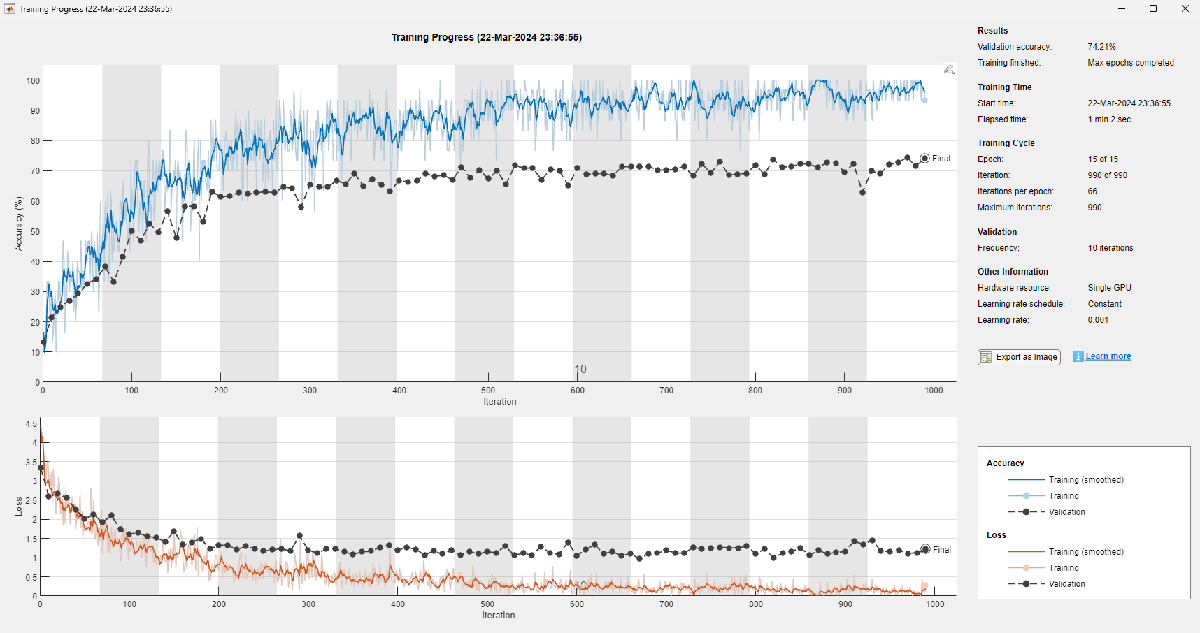

- 2nd Training

        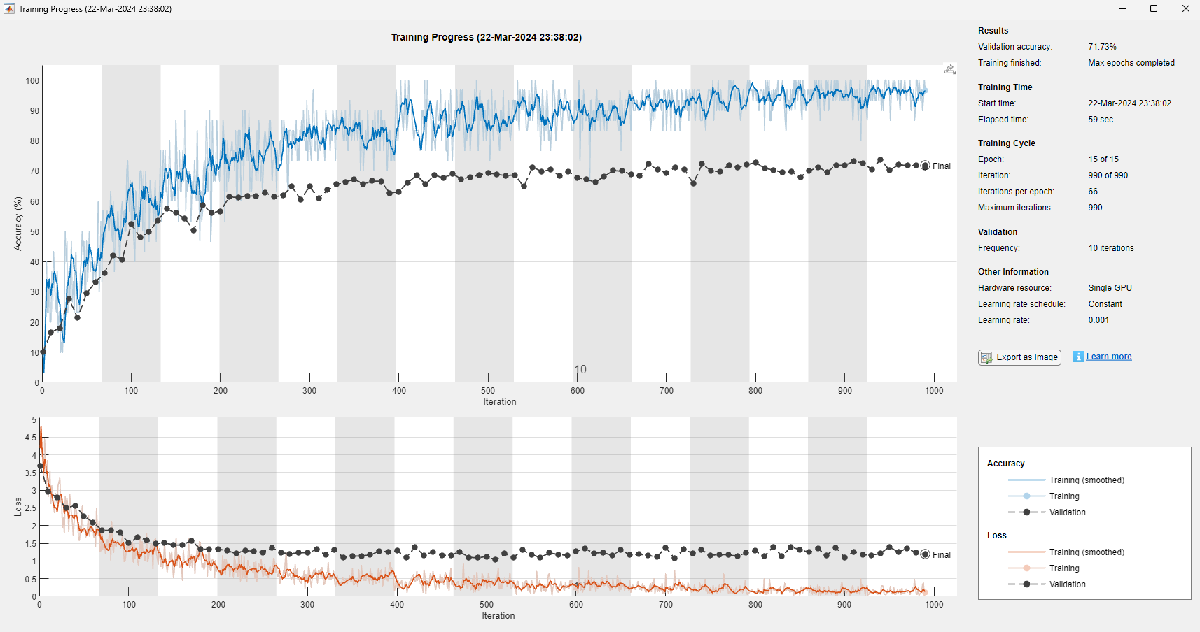

- 3rd Training

        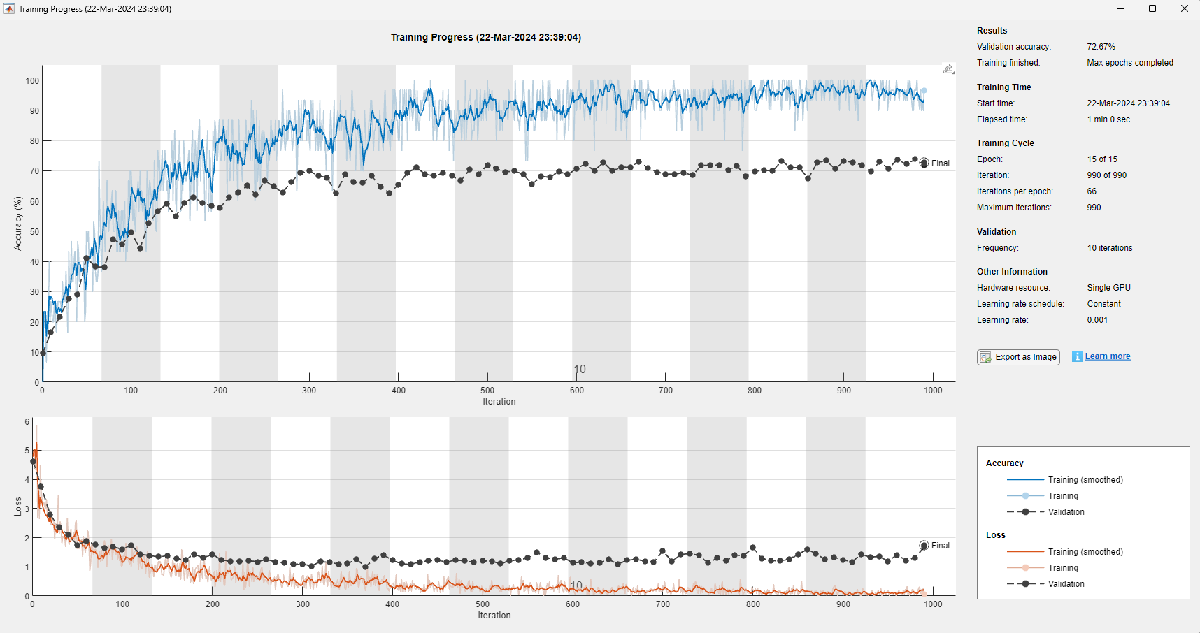

- 4th Training

        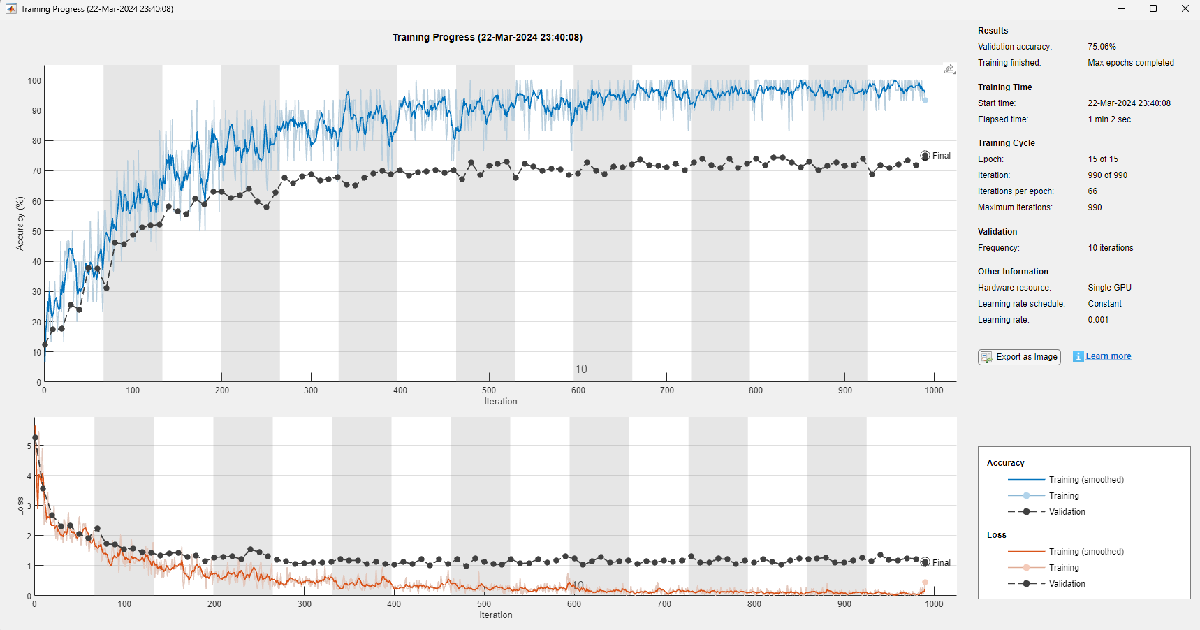

- 5th Training

        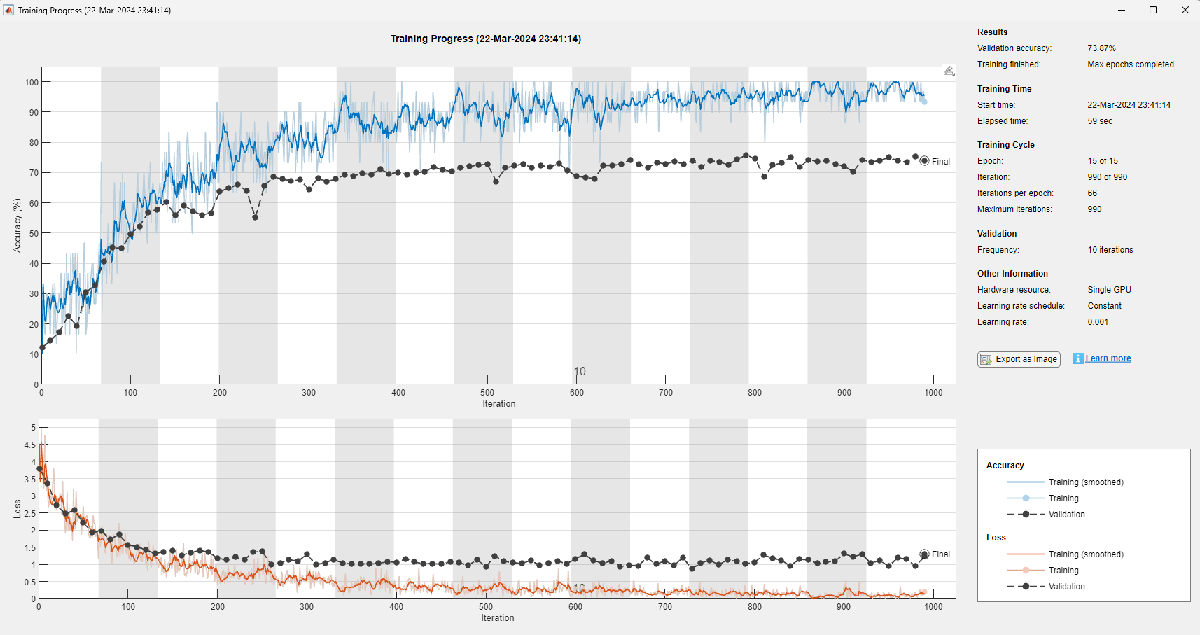

% execute the classification process using comparison with validation data
YPreds = cell(1, num_models);
for model_list = 1:num_models
    YPreds{model_index} = classify(models_list{model_index}, dsVal);
end

### 1.7 Execute Ensemble method and Accuracy

After all model has been stored in `YPreds`, each result of classification of the model will be most frequent prediction (mode). 

Finally, the ensemble accuracy achieved is `78.1383 %`, influenced by several key factors:

- The number of layers utilized in the models,

- The number of filters in each layer,

- The number of models combined through Bootstrap Aggregating (Bagging) technique.

The Result of Confusion Matrix 

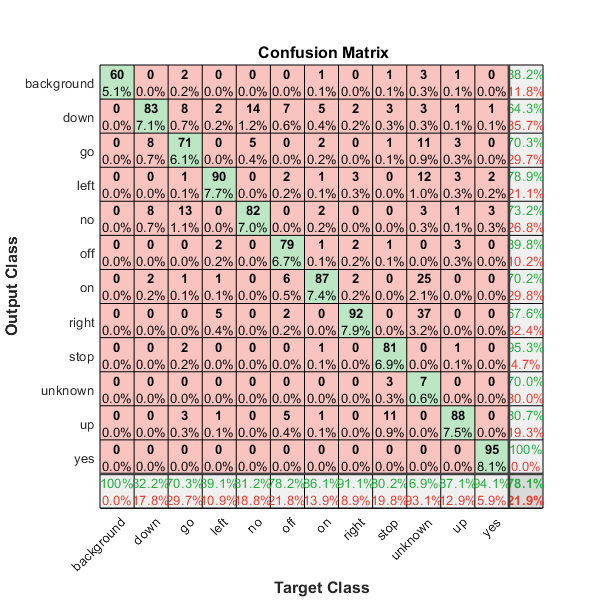

lgraph = layerGraph(net);  % Create a layer graph from the network
figure;
plot(lgraph);  % Plot the layer graph

% calculate the most frequent prediction
YPred = mode(cat(5, YPreds{:}), 5);

% extract ground truth labels
YVal = imdsVal.Labels;

% Calculate the accuracy  
accuracy = (sum(YPred == YVal)/numel(YVal))*100;
disp(['The accuracy is: ' num2str(accuracy)])

% plot confusion matrix
figure;
plotconfusion(YVal,YPred)

disp(["Set of Validation Accuracy: " num2str(accuracy) "%"]);

#### 1.7.1 Result of Modelling Prediction with Labelling the data  

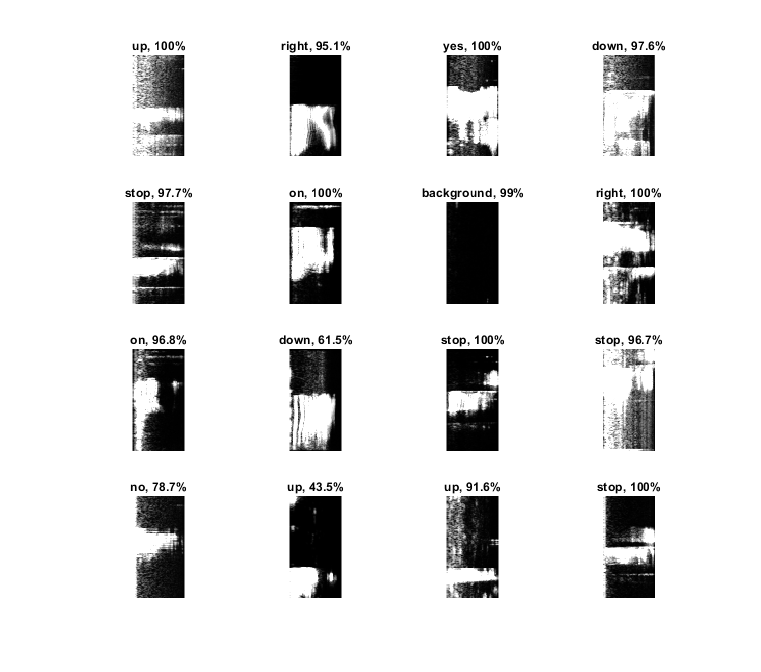

% Display sample test images with predicted labels and
% the predicted probabilities of the images having those labels.
idx = randperm(numel(imdsVal.Files),16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsVal,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label)+ ", "+num2str(100*max(probs(idx(i),:)),3)+"%");
end

### 1.8 Objective Function (Seperated Externally)